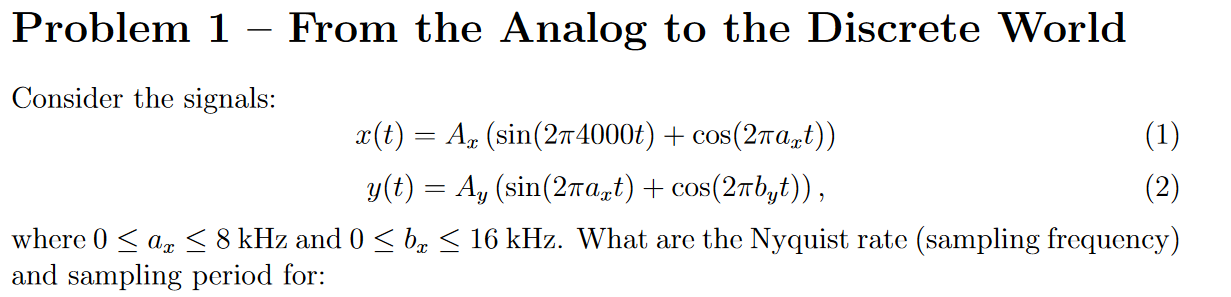

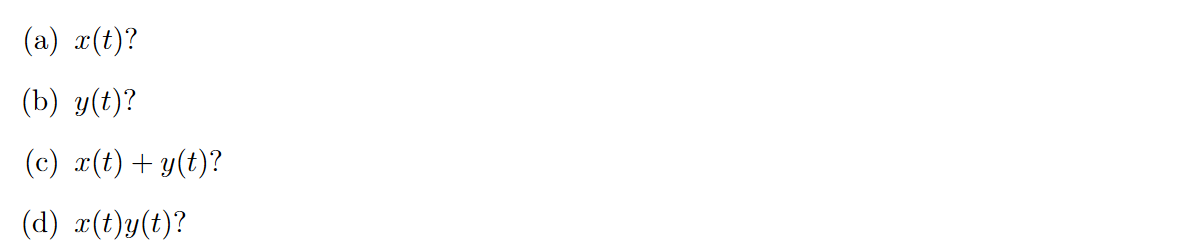 

A)

close all
clear
ax = 8E3;
axfreq = (2*ax*pi)/(2*pi)

axfreq =                       8000


axfreq*2

ans =                      16000


B)

bx = 16E3;
bxfreq = (2*bx*pi)/(2*pi);
bxfreq*2

ans =                      32000


c)

f)

close all
clear
% Parameters
Ax = 1;          % Amplitude, you can adjust this value
a_x = 8000;      % Frequency in Hz, you can adjust this value as well

% Continuous Time Vector for Smooth Plot
fs_continuous = 100000;           % High sampling frequency for smooth plot
t_continuous = 0:1/fs_continuous:0.001; % Time vector for continuous plot

% Discrete Time Vector for 16 samples over 1 ms
num_samples = 16;                 % Number of samples within 1 ms
t_samples = linspace(0, 0.001, num_samples); % 16 equally spaced points from 0 to 1 ms

% Continuous Signal Definition
x_t_continuous = Ax * (sin(2 * pi * 4000 * t_continuous) + cos(2 * pi * a_x * t_continuous));

% Sampled Signal Definition
x_t_samples = Ax * (sin(2 * pi * 4000 * t_samples) + cos(2 * pi * a_x * t_samples));

% Plotting
figure;
plot(t_continuous * 1000, x_t_continuous, 'b-', 'LineWidth', 1.5); % Continuous signal plot
hold on;
stem(t_samples * 1000, x_t_samples, 'r', 'LineWidth', 1.5); % Sampled signal plot
xlabel('Time (ms)');
ylabel('x(t)');
title('Plot of x(t) over 1 ms with 16 samples');
legend('Continuous Signal', 'Sampled Signal (16 samples)');
grid on;
hold off;

## Problem 2

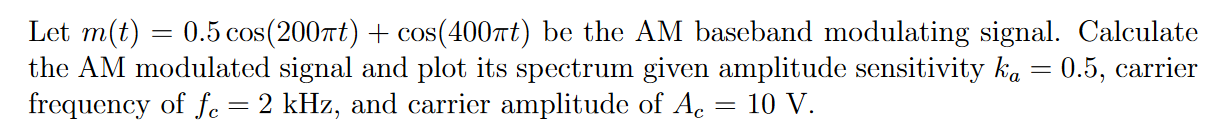

close all
clear
Fs = 6E3; %sample frequency
T = 1/Fs;
L = 6.5E3;
t = (0:L-1)*T;
fc = 2E3; %carrier frequency
Ac = 10;
Ka = 0.5;
m = 0.5*cos(200*pi*t)+cos(400*pi*t);
s = Ac.*(1+(Ka.*m)).*cos(fc.*2.*pi.*t); %am modulated signal.
y = fft(s);
plot(Fs/L*(0:L-1),abs(y),"LineWidth",3);

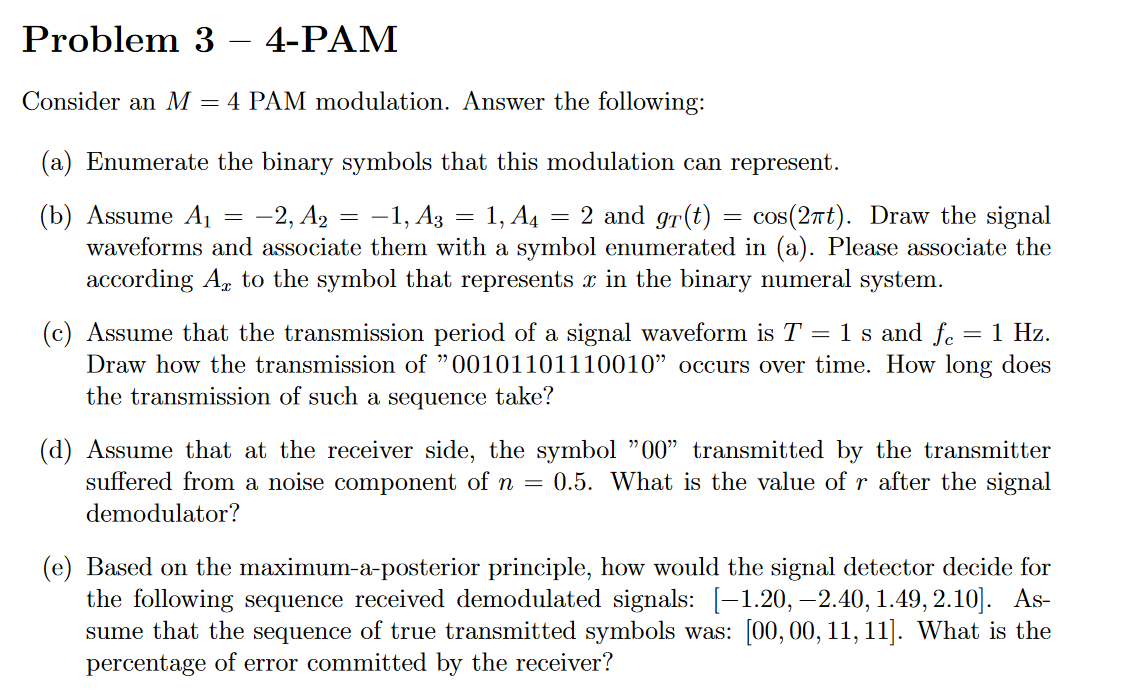

a) 

{00,01,10,11}